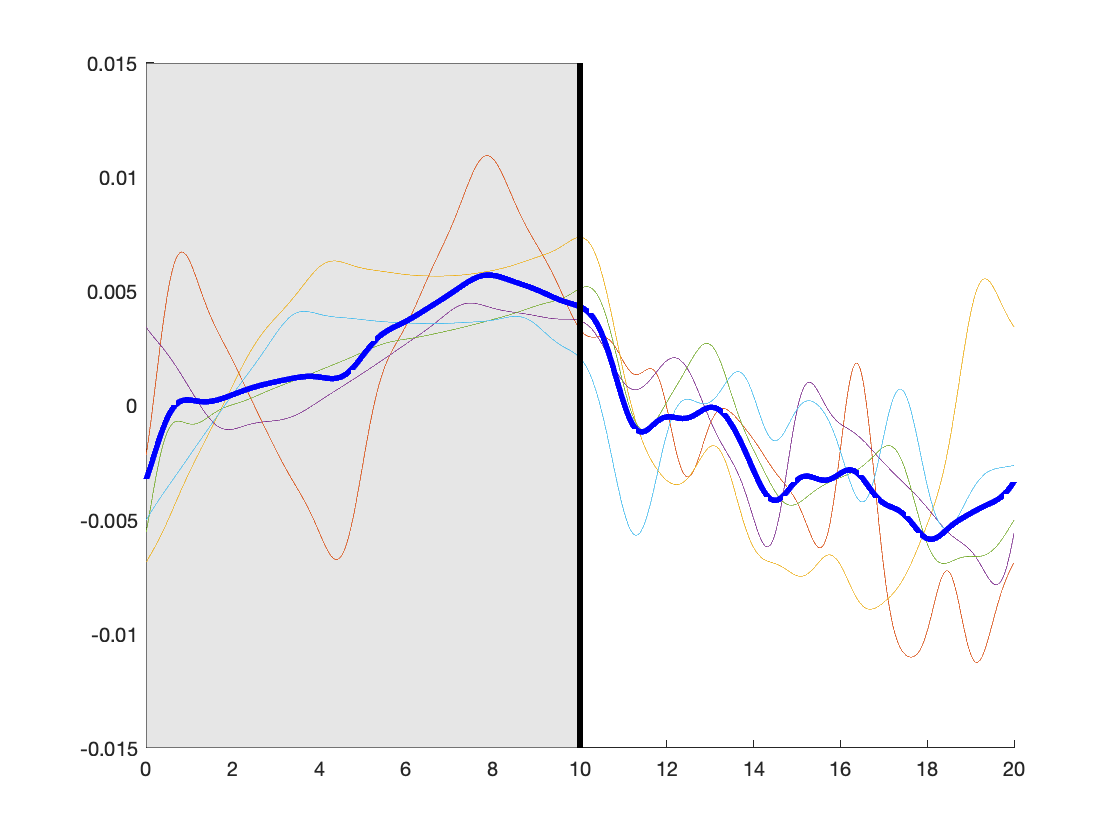

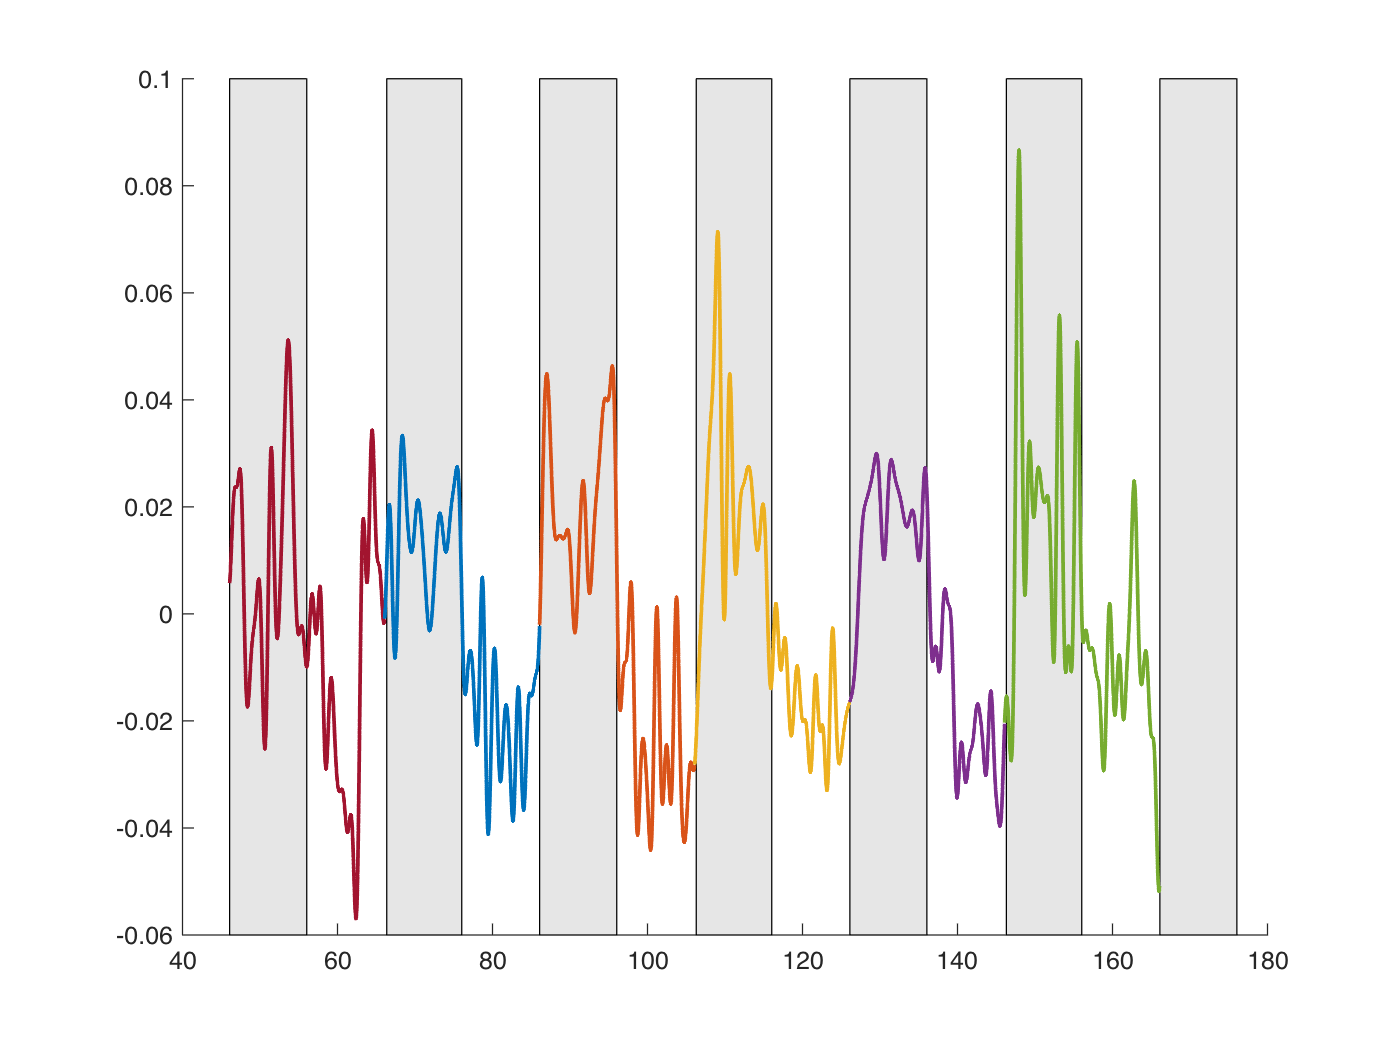

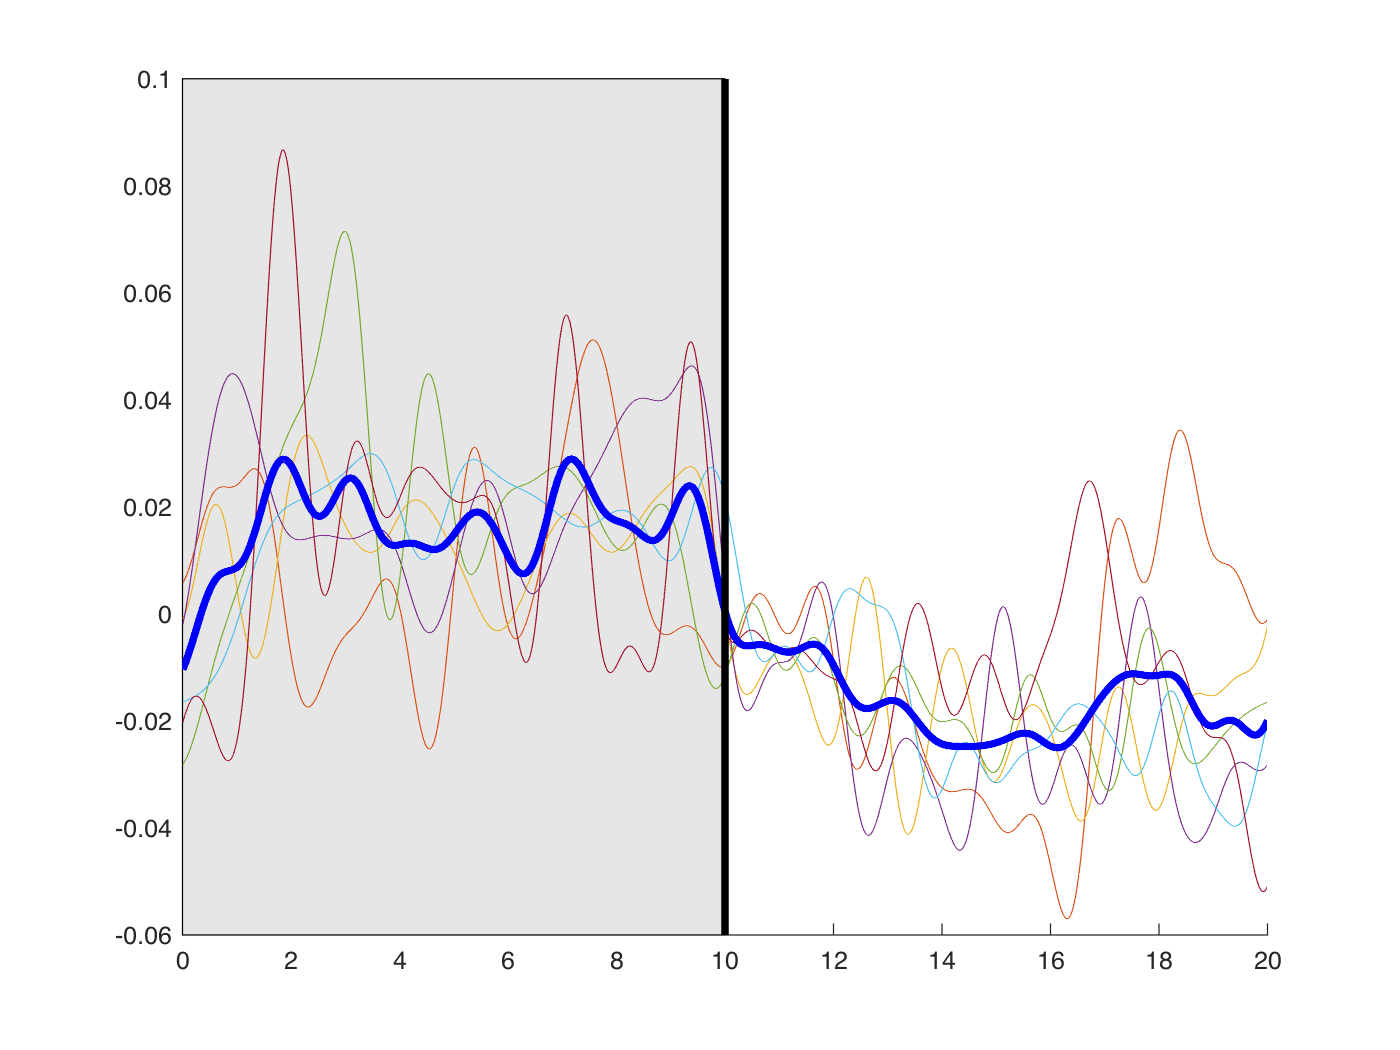

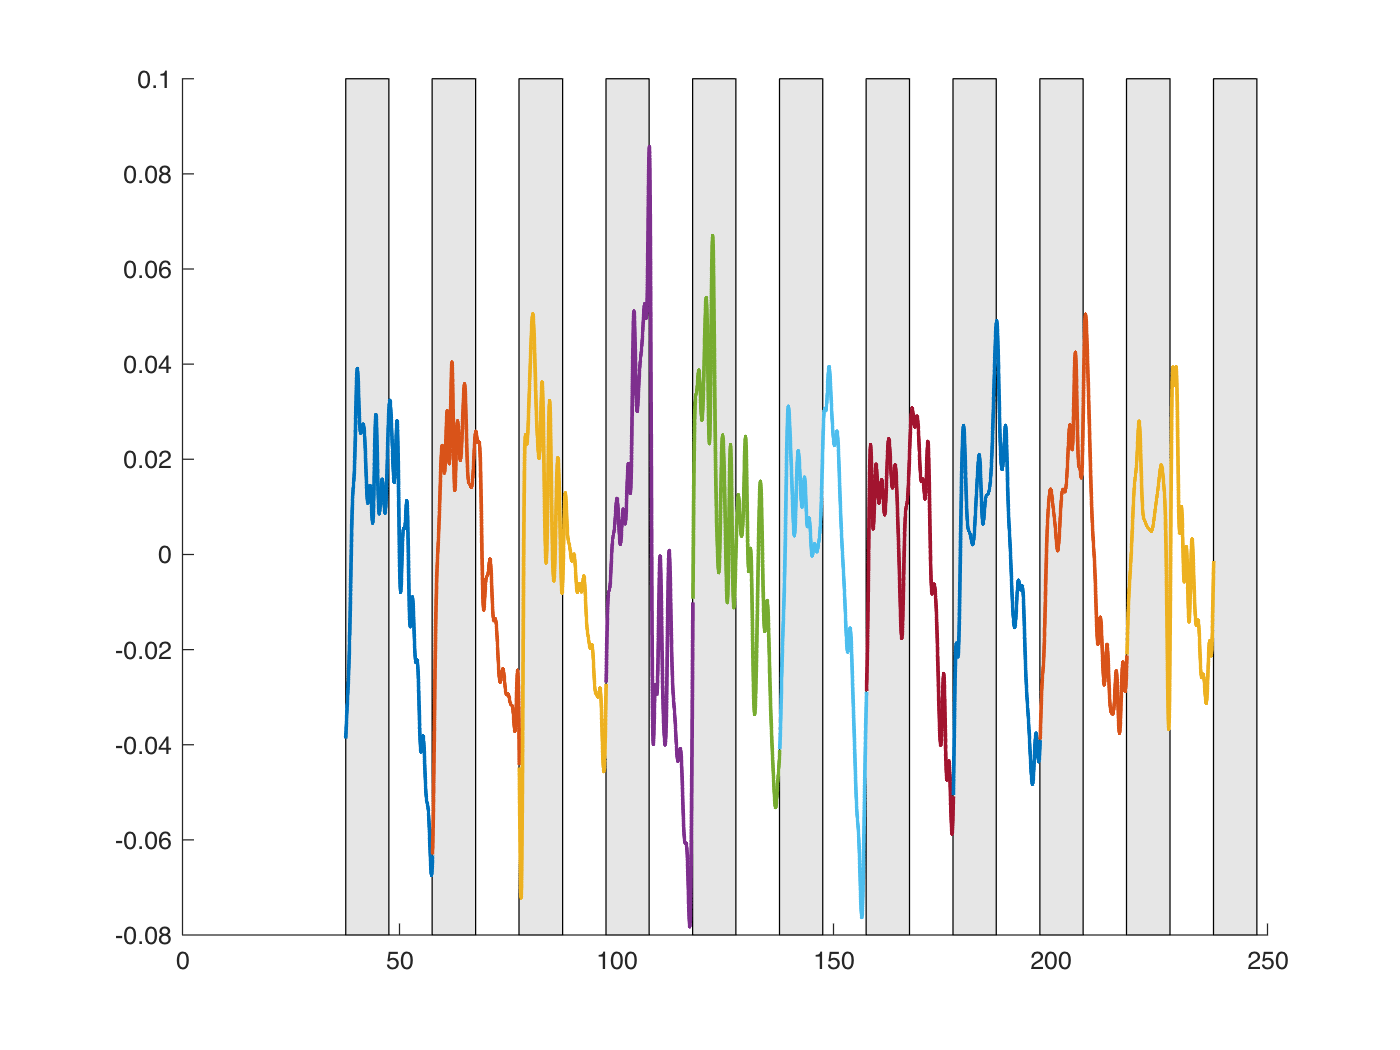

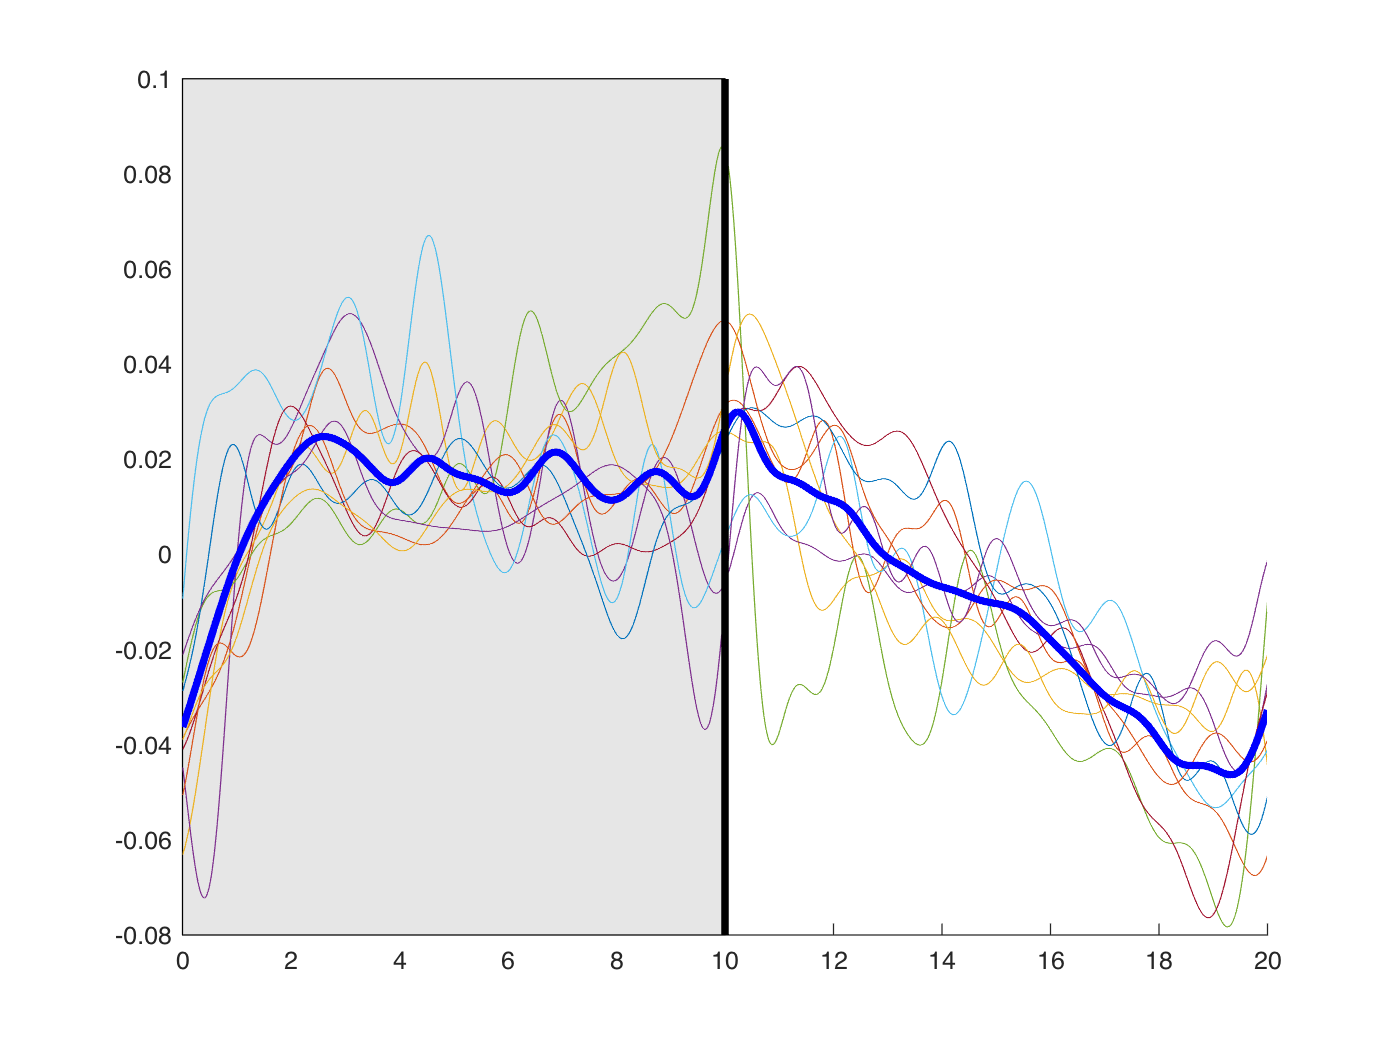

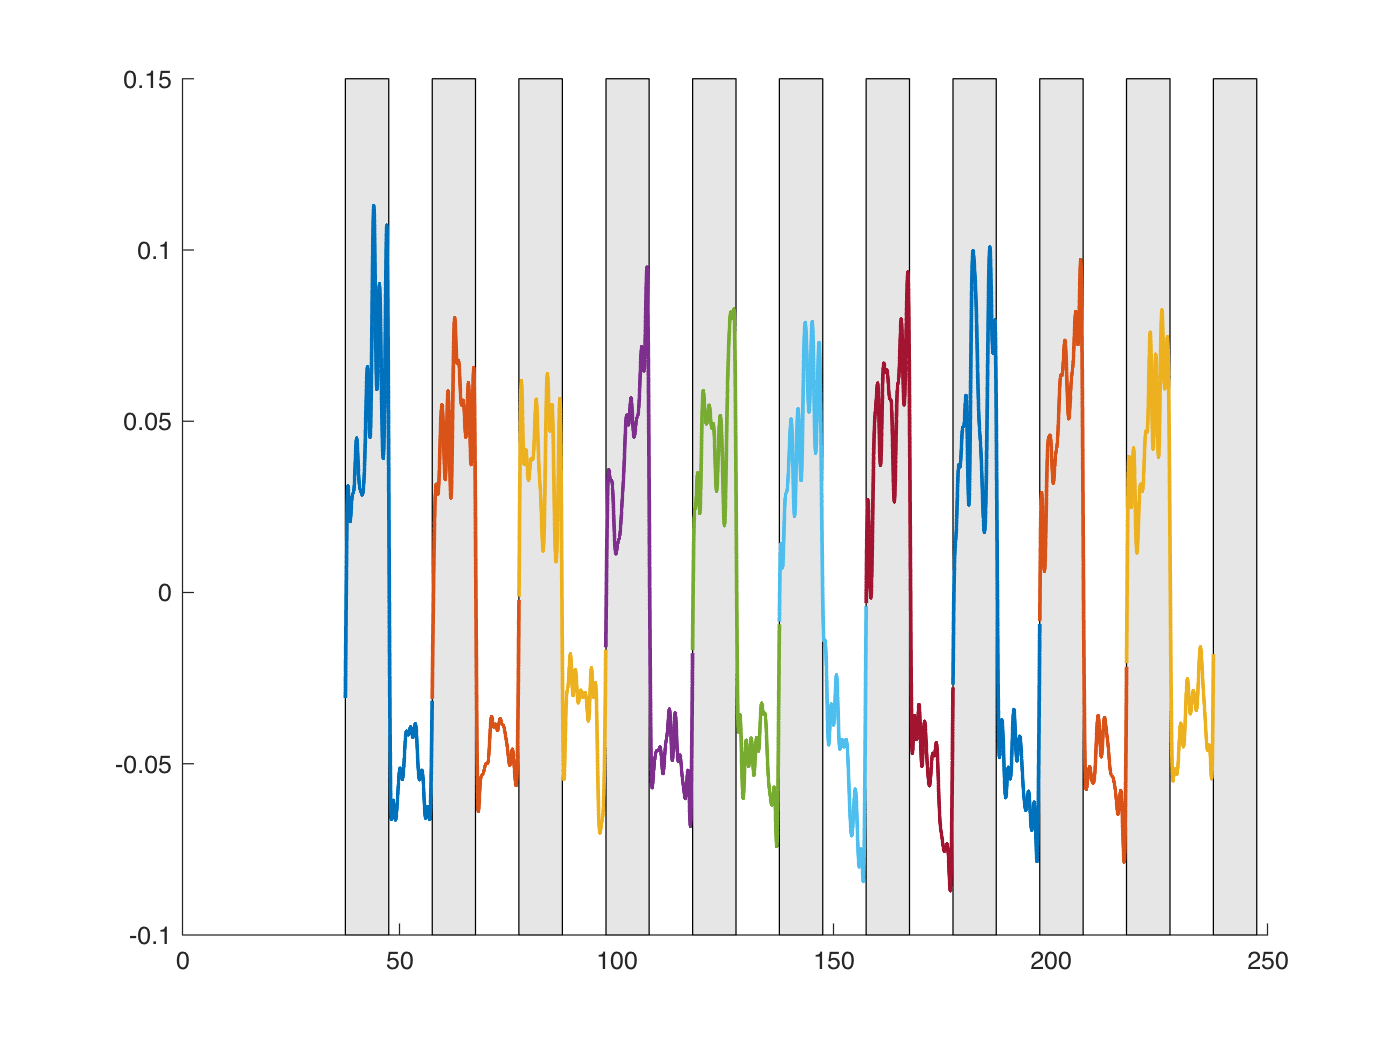

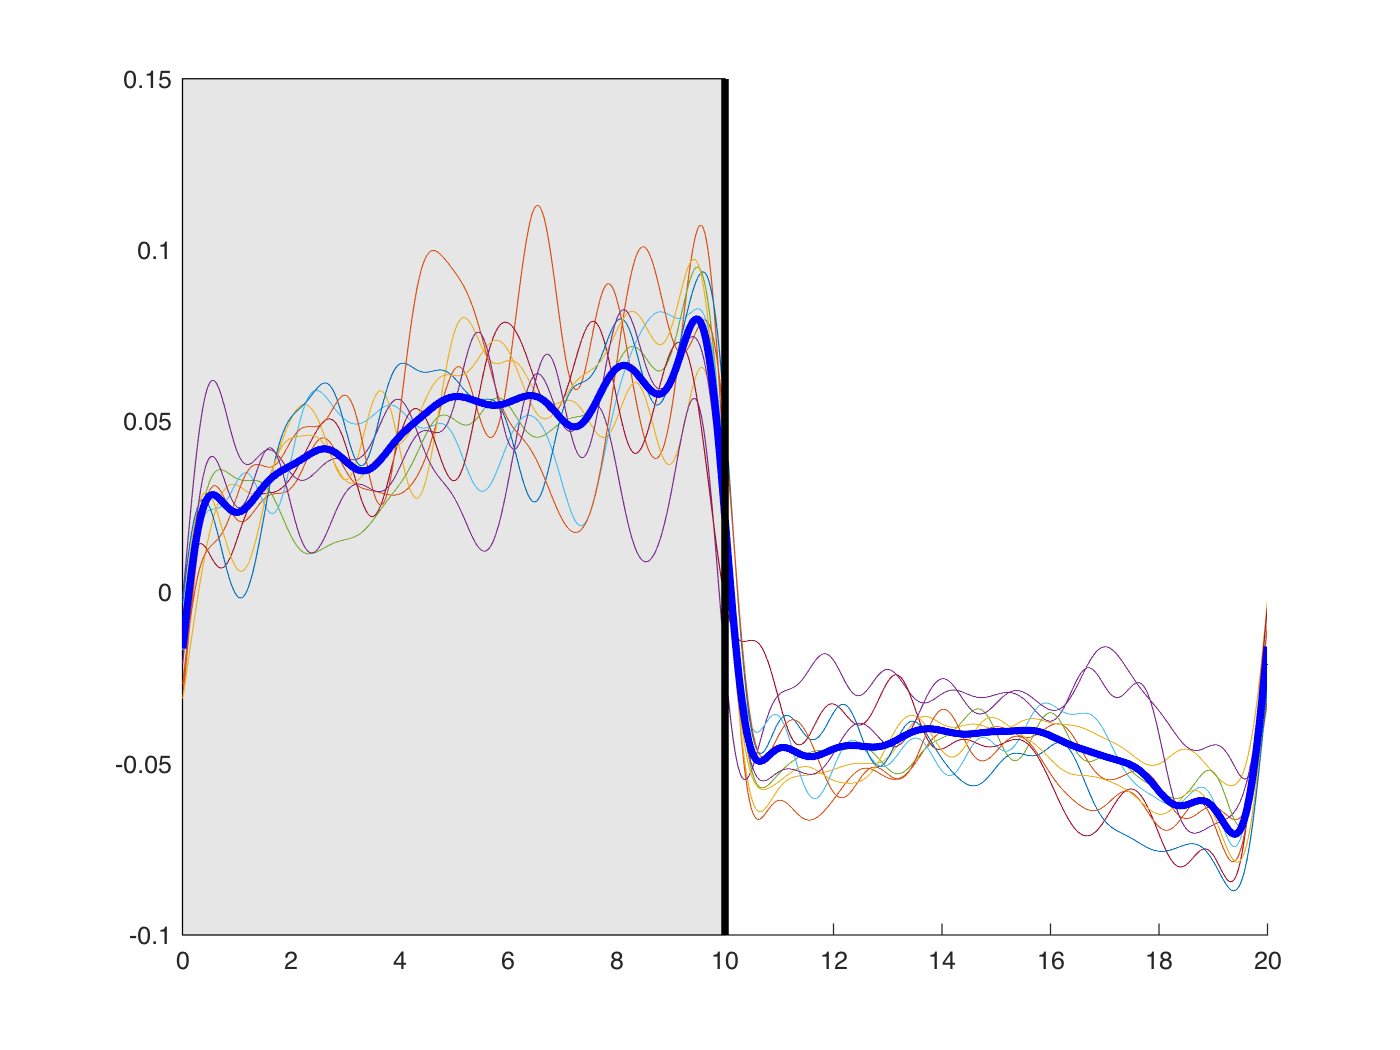

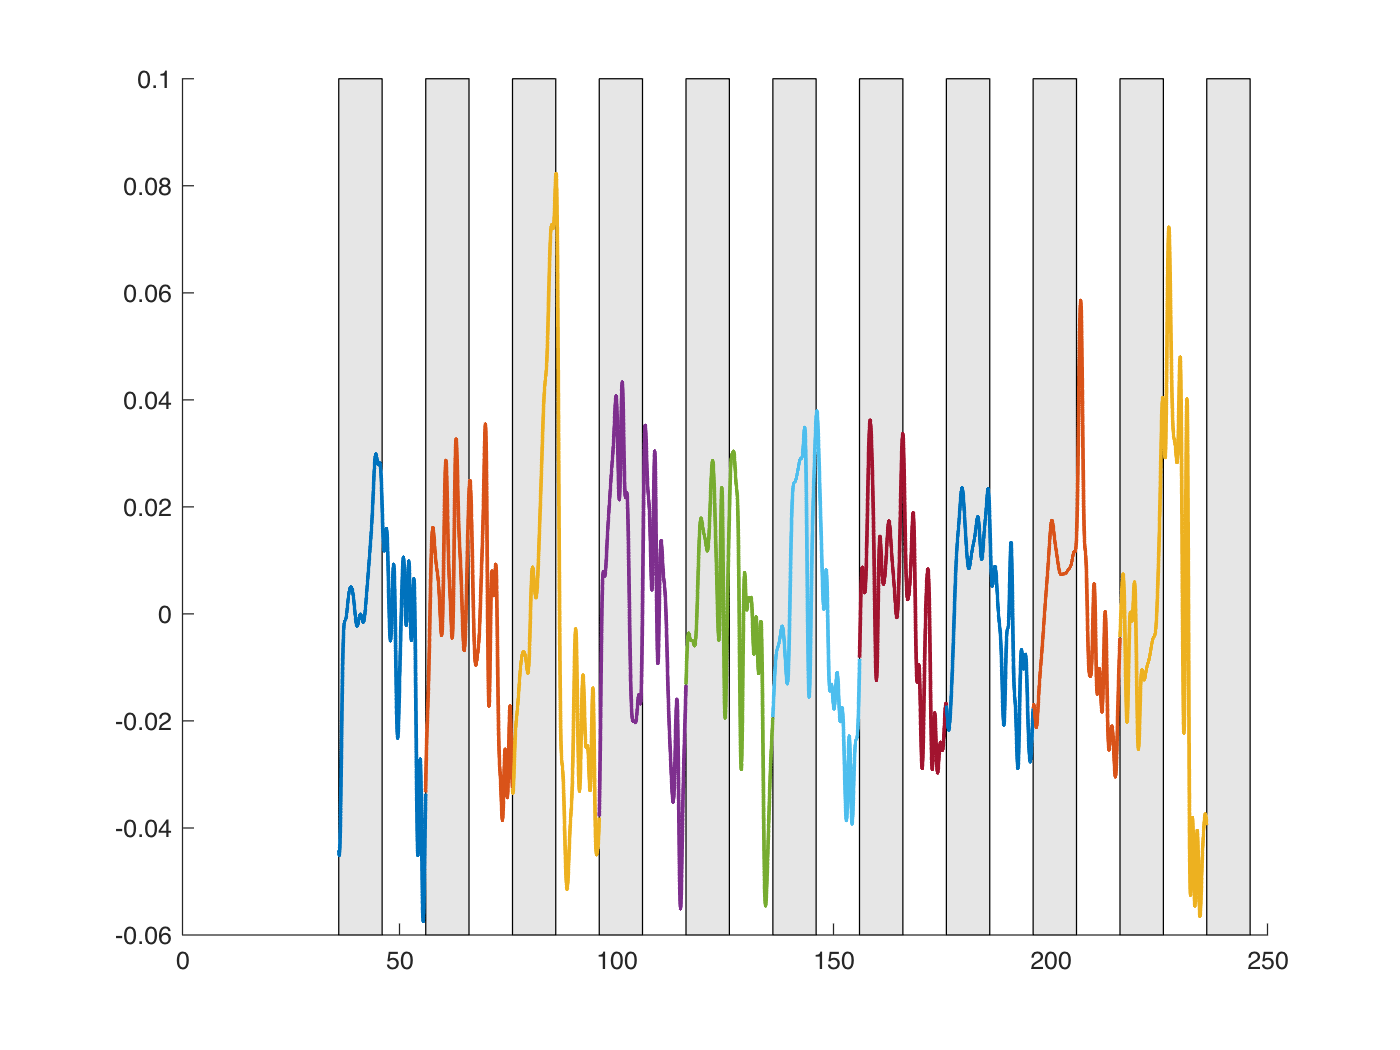

ReFs = 20;
ld = 10;



%10:10 LD
ten1idx= [6 7 60 61 86 88 89]; %60 is a mountain %61 multi modal? %88-would be wider poweridx with detrending 89 again with detrending
  
ten2idx = [87]; %61 outlier fish %60, 95
 

    for k = 1:length(ten1idx)
        tench1(k).day = KatieRegobwDayDessemblerhour(kg(ten1idx(k)), 1, ReFs, 3,k);
    end

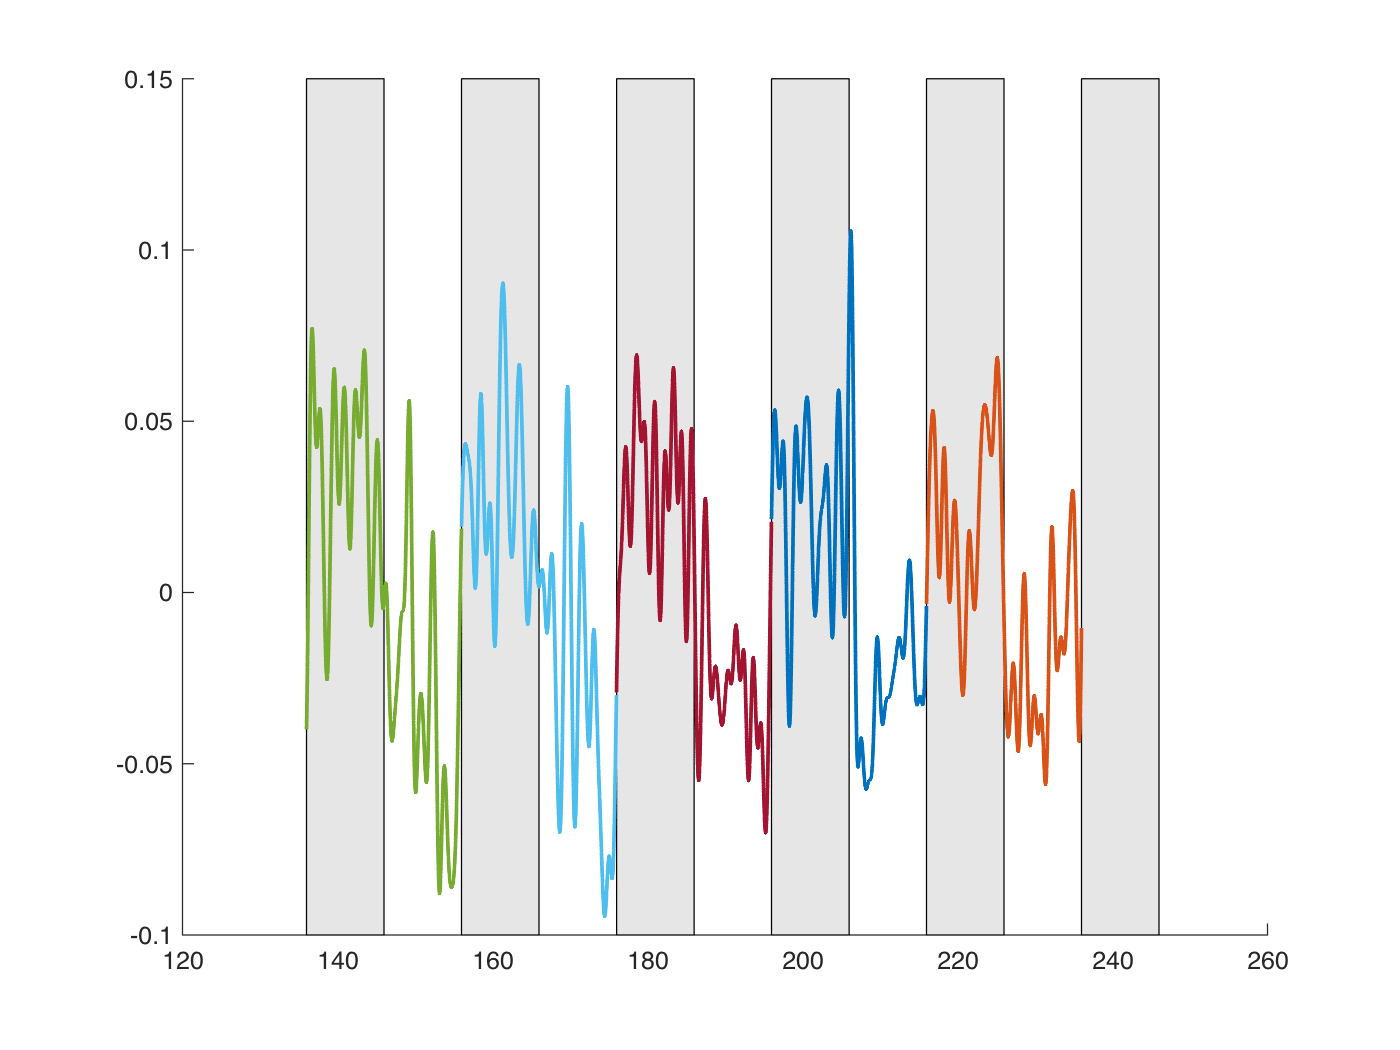

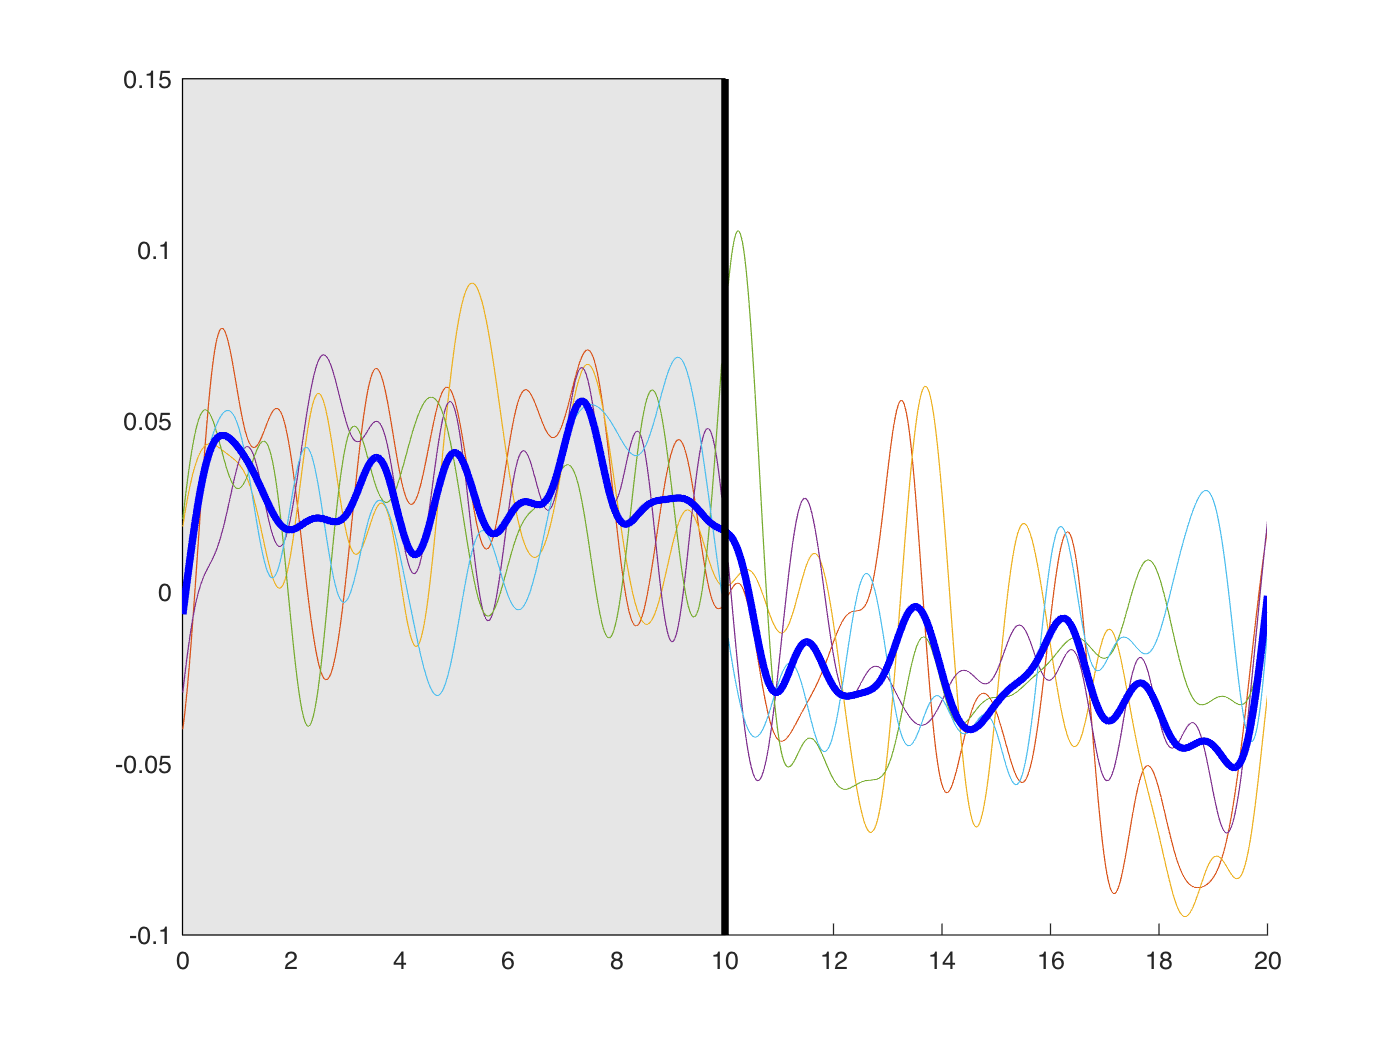


    for kk = 1:length(ten2idx)
        tench2(kk).day = KatieRegobwDayDessemblerhour(kg(ten2idx(kk)), 2, ReFs, 3,kk);
    end


    ten = [tench1 tench2];
    
    

[hourtim, meanofexperimentmeans, expavgrange, fish, ld] = k_fftdaymovabovemeans(ten)

hourtim =     0.0056    0.0111    0.0167    0.0222    0.0278    0.0333    0.0389    0.0444    0.0500    0.0556    0.0611    0.0667    0.0722    0.0778    0.0833    0.0889    0.0944    0.1000    0.1056    0.1111    0.1167    0.1222    0.1278    0.1333    0.1389    0.1444    0.1500    0.1556    0.1611    0.1667    0.1722    0.1778    0.1833    0.1889    0.1944    0.2000    0.2056    0.2111    0.2167    0.2222    0.2278    0.2333    0.2389    0.2444    0.2500    0.2556    0.2611    0.2667    0.2722    0.2778


meanofexperimentmeans =    -0.0169   -0.0167   -0.0166   -0.0162   -0.0159   -0.0156   -0.0153   -0.0149   -0.0146   -0.0143   -0.0140   -0.0136   -0.0133   -0.0130   -0.0127   -0.0123   -0.0120   -0.0117   -0.0114   -0.0111   -0.0107   -0.0104   -0.0101   -0.0098   -0.0095   -0.0092   -0.0088   -0.0085   -0.0082   -0.0079   -0.0076   -0.0073   -0.0070   -0.0067   -0.0064   -0.0061   -0.0058   -0.0055   -0.0052   -0.0049   -0.0046   -0.0044   -0.0041   -0.0038   -0.0035   -0.0032   -0.0030   -0.0027   -0.0024   -0.0022


expavgrange = 0.0997

fish = 1×8 struct array with fields:
    amprange


ld = 10

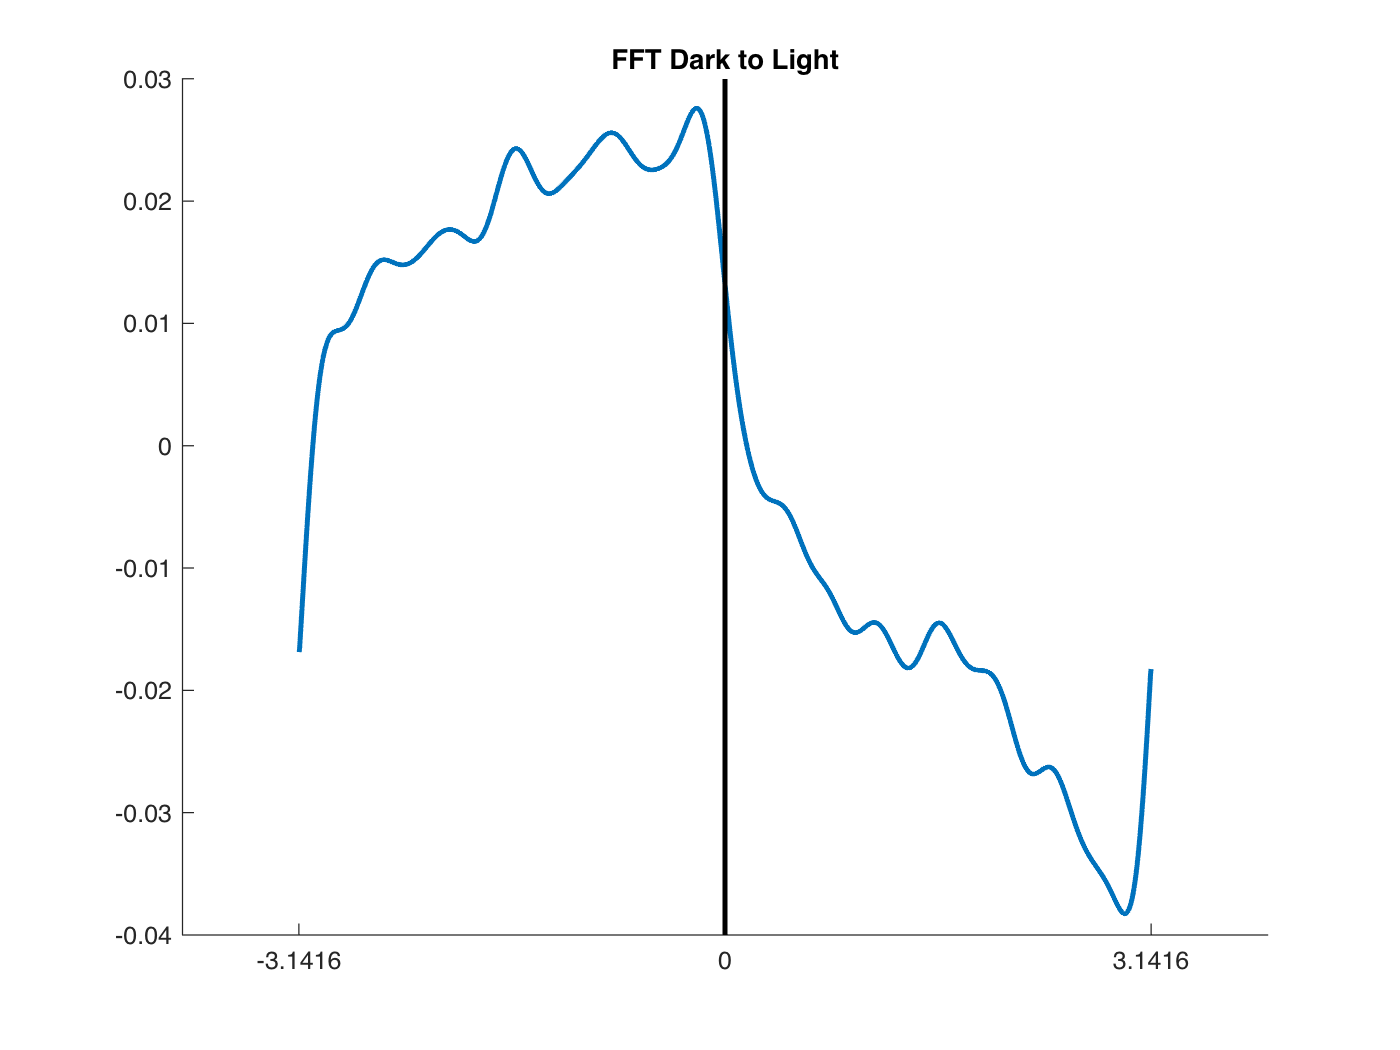

%plot
figure(317); clf; title('FFT Dark to Light'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

    
      
        %ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * ld);
        plot((hourtim .* crosshour)-pi, meanofexperimentmeans, 'LineWidth', 2)
       
  
    plot([0,0], ylim, 'k-', 'LineWidth', 2);

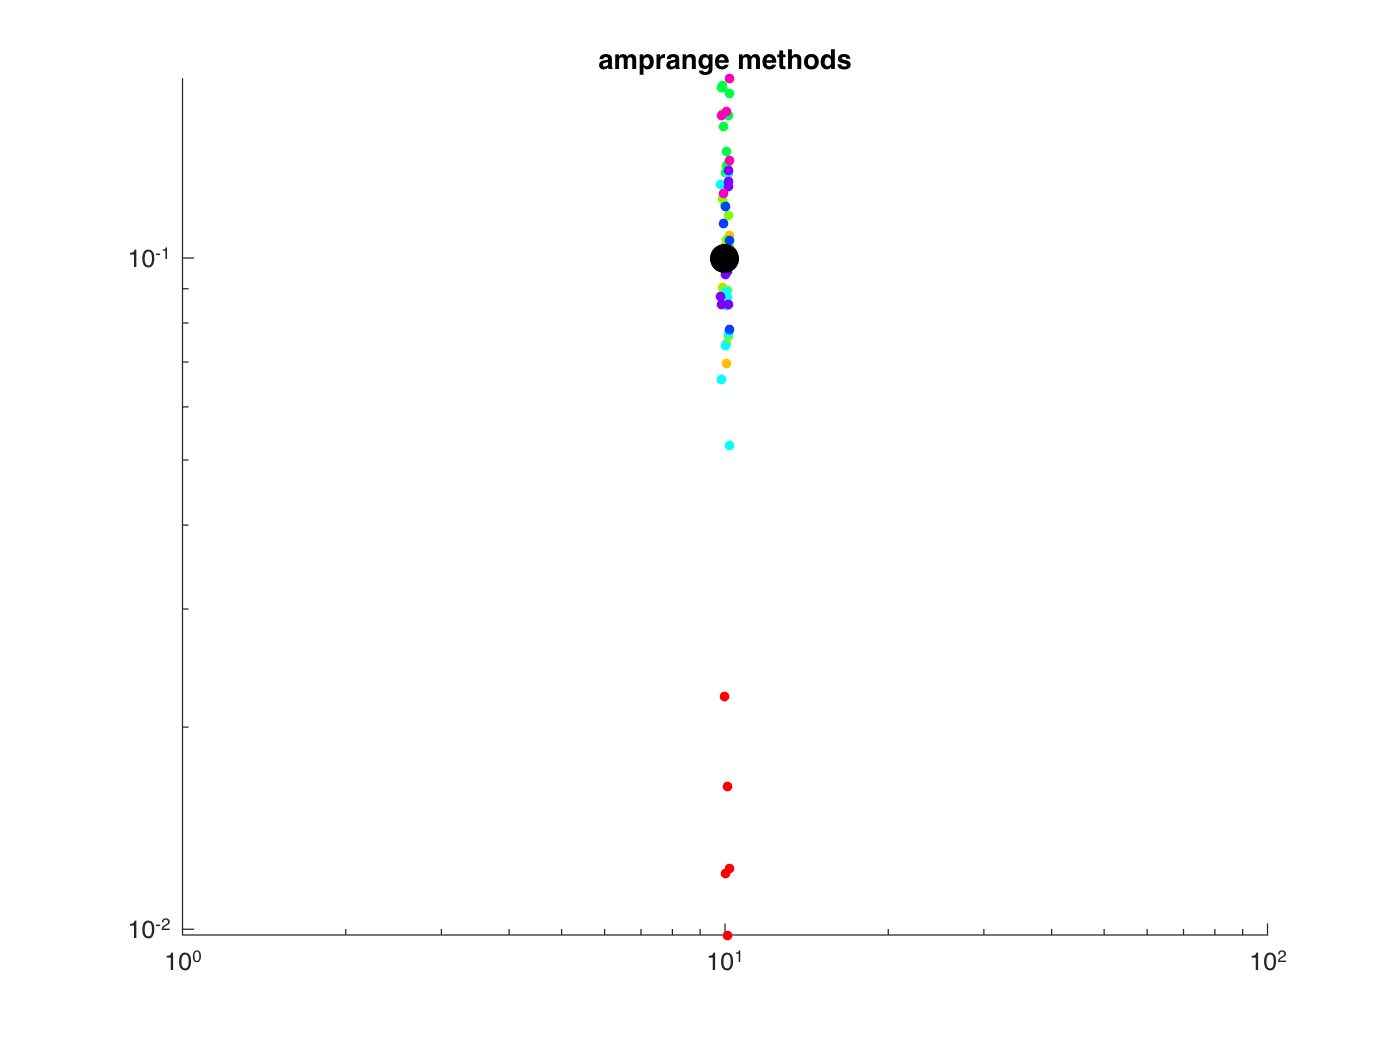


figure(98); clf; title('amprange methods'); hold on;

  

      
       
        for kk = 1:length(fish)
            clrbyfish = hsv(length(fish));
            for jj = 1:length(fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld, fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
        plot(ld, expavgrange, 'k.', 'MarkerSize', 35);

    
    set(gca,'xscale', 'log', 'yscale', 'log');

ReFs = 20;
ld = 48;
%48:48 LD
idx = [3 4 5 44 80 81 82 106];%[3 4 5 44 80 81 82 106]
                    %45 shit data - noise issues maybe
                    %46 left out for now - bit messy not too bad
                    %83 single day - kinda messy but not too bad
                    %102 single day (starts with light)
                    %107 messyeight
    
    for k = 1:length(foureightidx)
        k
        foureightdark(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 3, k);
       % foureightlight(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 4);
    end

Unrecognized function or variable 'foureightidx'.


    [hourtim, meanofexperimentmeans, hourampmax, ~] = k_fftdaymovabovemeans(foureightdark);


%plot
figure(317); clf; title('FFT Dark to Light'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

    
      
        %ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * ld);
        plot((hourtim .* crosshour)-pi, meanofexperimentmeans, 'LineWidth', 2)
       
  
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
   
